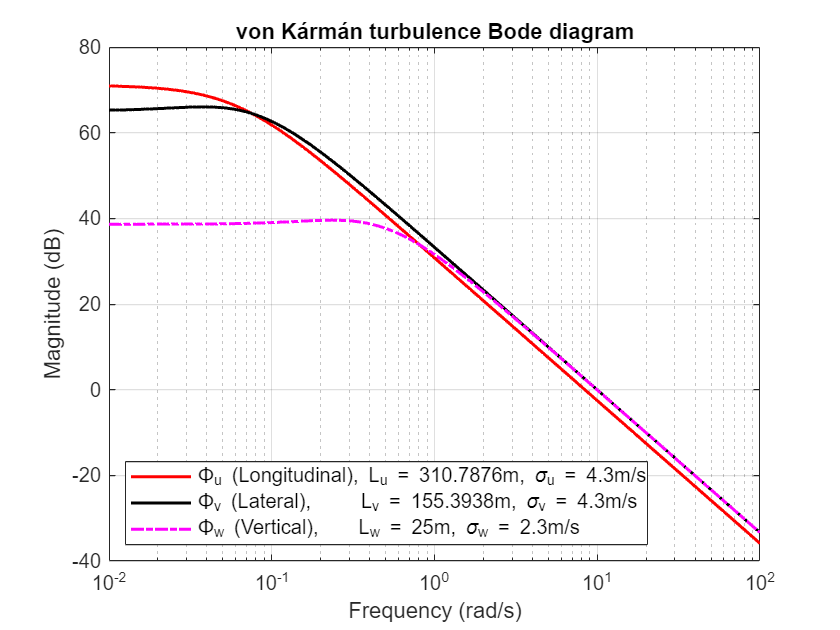

% von Karman spectra

clear; clc; close all;

% TURBULENCE MODEL: k-Epsilon model used to determine turbulence intensity
% and length scales
%% --- Parameters ---

h = 50;  % hover altitude (m)
V_hub = 25.7222;     % Mean wind speed at hub height (m/s) 
W20 = 23.15;  % Wind speed at 20 ft: severe turbulence W20 = 40 knots (23.15 m/s)

% USING MIL-HDBK-1797
Lw = h/2;    % Vertical turbulence length scale (m)
Lu = h/((0.177 + 0.000823*h)^1.2);       % Longitudinal turbulence length scale (m)  
Lv = Lu/2;    % Lateral turbulence length scale (m)

sigma_w = 0.1 * W20;     % Vertical turbulence intensity (m/s)
sigma_u = sigma_w / ((0.177 + 0.000823*h)^0.4); % Longitudinal turbulence intensity (standard deviation, m/s)
sigma_v = sigma_w /((0.177 + 0.000823*h)^0.4) ;     % Lateral turbulence intensity (m/s) 

%% --- Frequency Range ---
% f = logspace(-3, 2, 500); % Frequency range (Hz) - from 0.01 Hz to 100 Hz
% omega = 2 * pi * f;       % Spatial frequency (rad/s)

% f = linspace(0, 8*pi, 500); 
f = logspace(-2, 2, 500);
Omega = f / V_hub;

%% --- Von Karman Power Spectral Density Functions ---

% Longitudinal component (u)
Su_func = @(Omega, L, sigma) (2 * sigma^2 * L ./ pi) ./ ((1 + (1.339 * L * Omega).^2).^(5/6));

% Lateral handles (v)
Sv_func = @(Omega, L, sigma) (2 .* sigma^2 .* L ./ pi) .* (1 + (8/3).*(2.678 * L .* Omega).^2)./((1 + (2.678*L.*Omega).^2).^(11/6));
Sw_func = @(Omega, L, sigma) (2 .* sigma^2 .* L ./ pi) .* (1 + (8/3).*(2.678 * L .* Omega).^2)./((1 + (2.678*L.*Omega).^2).^(11/6));

%% --- Calculate PSDs ---
Phi_u_linear = Su_func(Omega, Lu, sigma_u);
Phi_v_linear = Sv_func(Omega, Lv, sigma_v);
Phi_w_linear = Sw_func(Omega, Lw, sigma_w);
% --- Convert PSD to dB
% Using a small epsilon to prevent log10(0) if any PSD value is extremely close to zero,
% though von Karman spectra are generally positive.
epsilon = 1e-12; % A small number to avoid log10(0)
Phi_u_dB = 20 * log10(Phi_u_linear + epsilon);
Phi_v_dB = 20 * log10(Phi_v_linear + epsilon);
Phi_w_dB = 20 * log10(Phi_w_linear + epsilon);

%% --- Plotting dB ---
figure;
semilogx(f, Phi_u_dB, 'r-', 'LineWidth', 1.5);
hold on;
semilogx(f, Phi_v_dB, 'black-', 'LineWidth', 1.5);
semilogx(f, Phi_w_dB, 'm-.', 'LineWidth', 1.5);
hold off;

% --- Formatting the Plot ---
title('von Kármán turbulence Bode diagram', 'FontSize', 14);
xlabel('Frequency (rad/s)', 'FontSize', 12);
ylabel('Magnitude (dB)', 'FontSize', 12); % Updated Y-label
legend({['\Phi_u (Longitudinal), L_u = ' num2str(Lu) 'm, \sigma_u = ' num2str(sigma_u,2) 'm/s'], ...
        ['\Phi_v (Lateral),     L_v = ' num2str(Lv) 'm, \sigma_v = ' num2str(sigma_v,2) 'm/s'], ...
        ['\Phi_w (Vertical),    L_w = ' num2str(Lw) 'm, \sigma_w = ' num2str(sigma_w,2) 'm/s']}, ...
        'Location', 'southwest', 'FontSize', 10); % A
grid on;
set(gca, 'FontSize', 10);
xlim([f(1) f(end)]); % Ensure the x-axis covers the defined frequency range

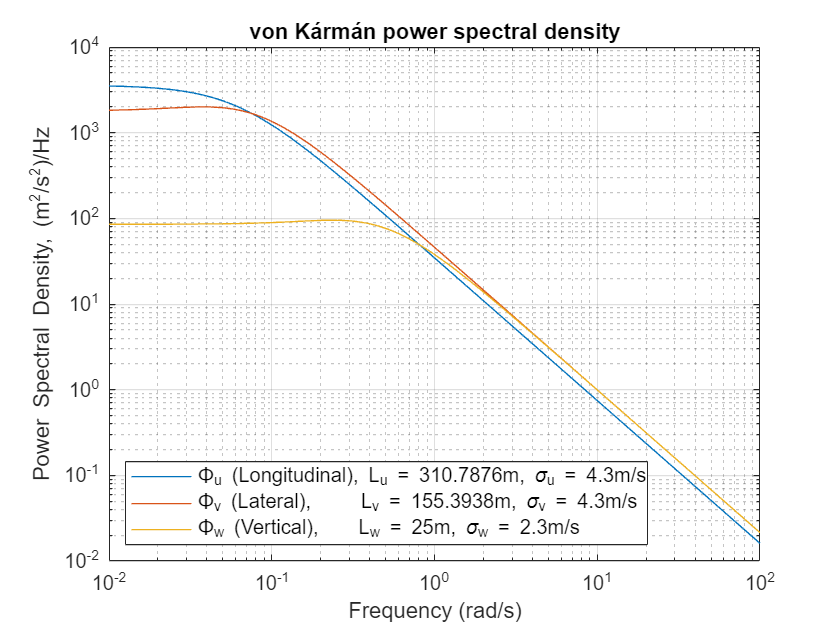



%% --- Plotting PSD ---
figure;
loglog(f, Phi_u_linear);
hold on;
loglog(f, Phi_v_linear);
loglog(f, Phi_w_linear);

hold off;

title("von Kármán power spectral density", "FontSize", 14);
xlabel("Frequency (rad/s)", "FontSize", 12);
ylabel("Power Spectral Density, (m^2/s^2)/Hz", "FontSize", 12);
legend({['\Phi_u (Longitudinal), L_u = ' num2str(Lu) 'm, \sigma_u = ' num2str(sigma_u,2) 'm/s'], ...
        ['\Phi_v (Lateral),     L_v = ' num2str(Lv) 'm, \sigma_v = ' num2str(sigma_v,2) 'm/s'], ...
        ['\Phi_w (Vertical),    L_w = ' num2str(Lw) 'm, \sigma_w = ' num2str(sigma_w,2) 'm/s']}, ...
        'Location', 'southwest', 'FontSize', 10); % A
grid on;
set(gca, 'FontSize', 10);

% %% --- Frequency Range ---
% f = logspace(-2, 2, 500); % Frequency range (Hz) - from 0.01 Hz to 100 Hz
% Omega = 2 * pi * f;       % Angular frequency (rad/s)
% 
% %% --- Von Karman Power Spectral Density Functions ---
% 
% % Longitudinal component (u)
% Su = @(omega, V, L, sigma) (2 * sigma^2 * L / V) ./ (1 + (1.339 * L * omega ./ V).^2).^(5/6);
% 
% % Lateral component (v)
% Sv_term1 = @(omega, V, L, sigma) (sigma^2 * L / V);
% Sv_num_term2 = @(omega, V, L) (1 + (4/3) * (1.339 * L * omega ./ V).^2);
% Sv_den = @(omega, V, L) (1 + (1.339 * L * omega ./ V).^2).^(11/6);
% Sv = @(omega, V, L, sigma) Sv_term1(omega, V, L, sigma) .* Sv_num_term2(omega, V, L) ./ Sv_den(omega, V, L);
% 
% % Vertical component (w)
% % The vertical component has the same functional form as the lateral component
% % if Lv = Lw and sigma_v = sigma_w. For generality, we'll write it separately.
% Sw_num_term1 = @(omega, V, L, sigma) (sigma^2 * L / V);
% Sw_num_term2 = @(omega, V, L) (1 + (4/3) * (1.339 * L * omega ./ V).^2);
% Sw_den = @(omega, V, L) (1 + (1.339 * L * omega ./ V).^2).^(11/6);
% Sw = @(omega, V, L, sigma) Sw_num_term1(omega, V, L, sigma) .* Sw_num_term2(omega, V, L) ./ Sw_den(omega, V, L);
% 
% 
% %% --- Calculate PSDs ---
% Phi_u = Su(Omega, V_hub, Lu, sigma_u);
% Phi_v = Sv(Omega, V_hub, Lv, sigma_v);
% Phi_w = Sw(Omega, V_hub, Lw, sigma_w);
% 
% %% --- Plotting ---
% figure;
% loglog(f, Phi_u, 'r-', 'LineWidth', 1.5);
% hold on;
% loglog(f, Phi_v, 'g--', 'LineWidth', 1.5);
% loglog(f, Phi_w, 'b-.', 'LineWidth', 1.5);
% hold off;
% 
% % --- Formatting the Plot ---
% title('Von Karman Wind Turbulence Power Spectra for Helicopter', 'FontSize', 14);
% xlabel('Frequency (Hz)', 'FontSize', 12);
% ylabel('Power Spectral Density (m^2/s^2/Hz)', 'FontSize', 12);
% legend({['\Phi_u (Longitudinal), L_u = ' num2str(Lu) 'm, \sigma_u = ' num2str(sigma_u,2) 'm/s'], ...
%         ['\Phi_v (Lateral),     L_v = ' num2str(Lv) 'm, \sigma_v = ' num2str(sigma_v,2) 'm/s'], ...
%         ['\Phi_w (Vertical),    L_w = ' num2str(Lw) 'm, \sigma_w = ' num2str(sigma_w,2) 'm/s']}, ...
%         'Location', 'southwest', 'FontSize', 10);
% grid on;
% set(gca, 'FontSize', 10);
% xlim([f(1) f(end)]); % Ensure the x-axis covers the defined frequency range
% 
% % --- Display Parameters on Plot (Optional) ---
% dim = [.2 .5 .3 .3]; % Position for text box [x y w h]
% str = {['Mean Wind Speed (V_{hub}): ' num2str(V_hub) ' m/s']};
% annotation('textbox',dim,'String',str,'FitBoxToText','on', 'BackgroundColor', 'white');

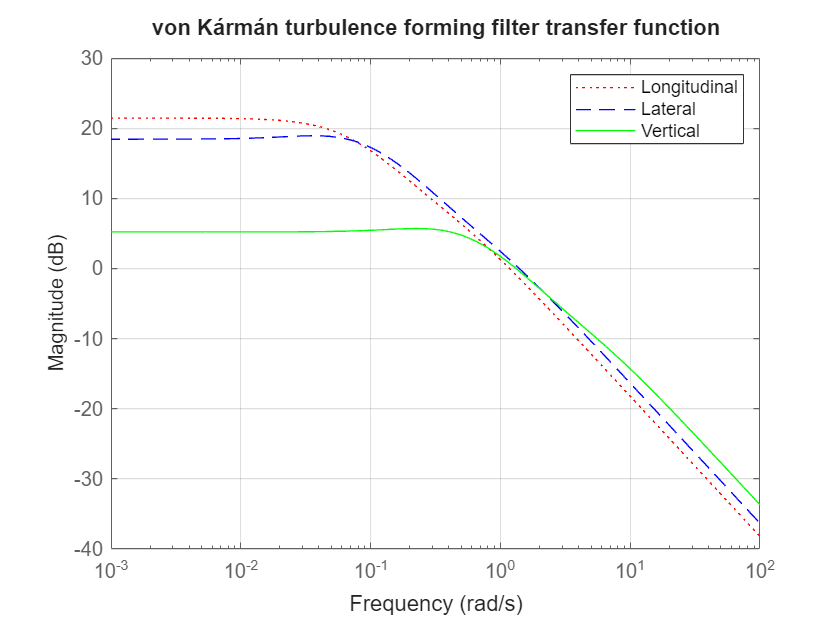

% --- Numerical Example ---
% Assign example values to the parameters

% Calculate the ratio
V = V_hub;
Lu_V_ratio = Lu / V;
Lv_V_ratio = 2*Lv / V;
Lw_V_ratio = 2*Lw / V;

% Numerator Coefficients
coeff_u = sigma_u*sqrt(2*Lu_V_ratio/pi);
coeff_v = sigma_v*sqrt(Lv_V_ratio/pi);
coeff_w = sigma_w*sqrt(Lw_V_ratio/pi);

num_u = [0.25*coeff_u*Lu_V_ratio, coeff_u];
num_v = [0.3398 * Lv_V_ratio^2 * coeff_v, 2.7478 * coeff_v * Lv_V_ratio, coeff_v];
num_w = [0.3398 * Lw_V_ratio^2 * coeff_w, 2.7478 * coeff_w * Lw_V_ratio, coeff_w]; 

% Denominator Coefficients
den_u = [0.1987*(Lu_V_ratio^2), 1.357*Lu_V_ratio, 1]; 
den_v = [0.1539*(Lv_V_ratio)^3, 1.9754*(Lv_V_ratio)^2, 2.9958*Lv_V_ratio, 1];
den_w = [0.1539*(Lw_V_ratio)^3, 1.9754*(Lw_V_ratio)^2, 2.9958*Lw_V_ratio, 1];

% Create the transfer function object
Hu = tf(num_u, den_u);
Hv = tf(num_v, den_v);
Hw = tf(num_w, den_w);

% Adding Gaussian white noise

bodemag(Hu, "r:")
hold on; grid on;
bodemag(Hv, "b--")
bodemag(Hw, "g")
hold off
title("von Kármán turbulence forming filter transfer function")
legend("Longitudinal", "Lateral", "Vertical")

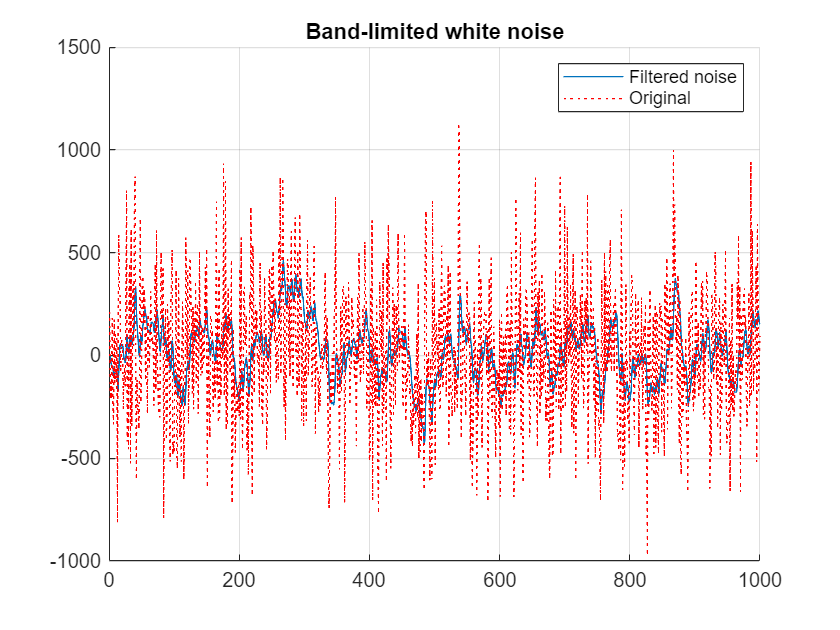

% PSD - forming coloured noise with additive Gaussian noise
clf
fs = 10;
t_duration = 100;
num_samples = 1000;
num_variables = 3;
noise = wgn(num_samples, num_variables,  50);

t =  (0:num_samples-1)'/fs;
% cu_noise = lsim(Hu, noise(:, 1), t);
% plot(cu_noise)
grid on
hold on
cv_noise = lsim(Hw, noise(:, 2), t);
% cw_noise = lsim(Hv, noise(:, 3), t);
% plot(cw_noise)
aa = plot(cv_noise);
bb = plot(noise(:, 2), 'r:');
title("Band-limited white noise")
legend("Filtered noise", "Original")


tester = noise(:, 2);
v_fft = fft(tester);
N = length(tester);
v_fft = vfft(1:N/2+1);
psdx = (1/(fs*N)) * abs(v_fft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(cv_noise):fs/2;
freq = freq/(2*pi);

hold off

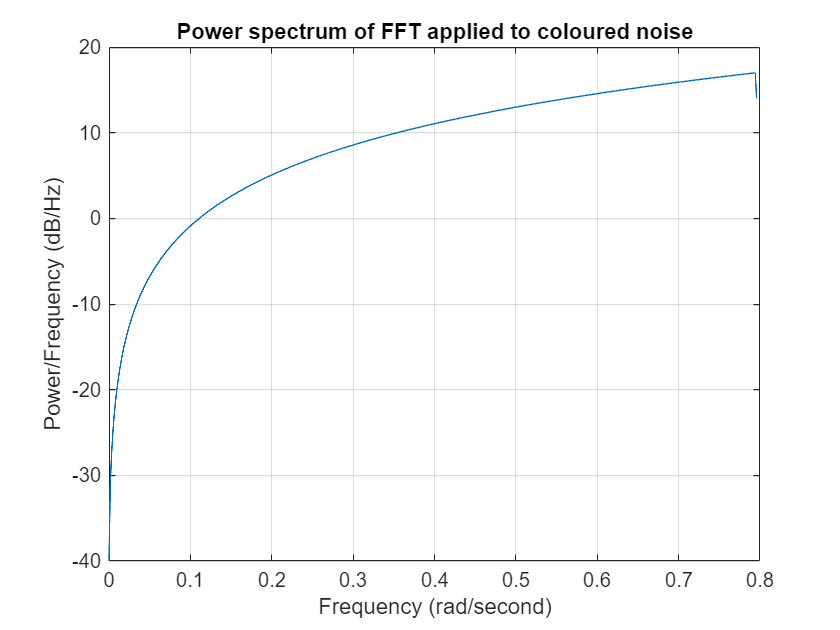

plot(freq, pow2db(psdx))

grid on
xlabel("Frequency (rad/second)")
ylabel("Power/Frequency (dB/Hz)")
title("Power spectrum of FFT applied to coloured noise")

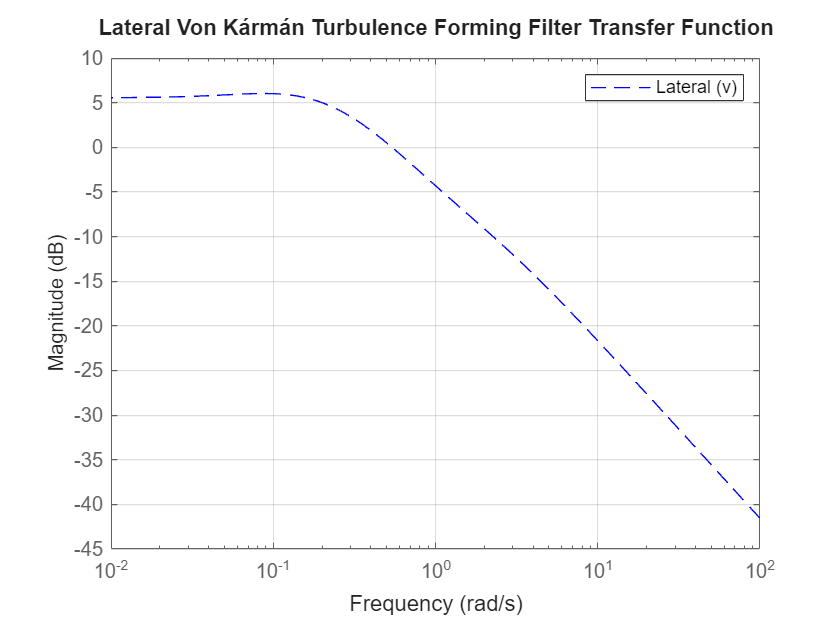

% This script simulates the lateral component of atmospheric turbulence using
% the von Karman gust model.
% 1. It defines the necessary physical parameters for a given wind condition.
% 2. It implements the von Karman shaping filter for the lateral gust (v).
% 3. It generates White Gaussian Noise (WGN) as an input.
% 4. It passes the WGN through the filter to generate the v_gust component.
% 5. It plots the filter characteristics (Bode plot) and the resulting
%    Power Spectral Density (PSD) of the lateral turbulence data.

% --- 1. DEFINE PHYSICAL & SIMULATION PARAMETERS ---

% Assign example physical values for the model
V_hub = 20;             % Hub wind speed (m/s)
Lu = 200;               % Longitudinal turbulence scale length (m)
Lv = 50;                % Lateral turbulence scale length (m)
Lw = 20;                % Vertical turbulence scale length (m)
sigma_u = 2.0;          % Longitudinal turbulence intensity (m/s)
sigma_v = 1.5;          % Lateral turbulence intensity (m/s)
sigma_w = 1.0;          % Vertical turbulence intensity (m/s)

% Simulation parameters
fs = 100;               % Sampling frequency (Hz)
t_duration = 600;       % Duration of the simulation (seconds) - increased for better PSD resolution
M = fs * t_duration;    % Total number of samples
t = (0:M-1)' / fs;      % Time vector

% --- 2. DEFINE LATERAL VON KARMAN FORMING FILTER ---
% This section defines the transfer function for the lateral gust component.

% Calculate the time-scale ratio
V = V_hub;
Lv_V_ratio = 2*Lv / V; % Note: The factor of 2 is often used for lateral/vertical components

% Numerator Coefficients
coeff_v = sigma_v * sqrt(Lv_V_ratio / pi);
num_v = [0.3398 * Lv_V_ratio^2 * coeff_v, 2.7478 * coeff_v * Lv_V_ratio, coeff_v];

% Denominator Coefficients
den_v = [0.1539*(Lv_V_ratio)^3, 1.9754*(Lv_V_ratio)^2, 2.9958*Lv_V_ratio, 1];

% Create the transfer function object for the lateral component
Hv = tf(num_v, den_v);

% --- 3. GENERATE WHITE NOISE AND FILTER IT ---

% Generate an M x 1 vector of White Gaussian Noise for the lateral input
% wgn_input_v = randn(M, 1);
wgn_input_v = wgn(M, 1, 49);

% Pass the noise signal through its corresponding transfer function
% lsim simulates the time response of a continuous-time system to the input
v_gust = lsim(Hv, wgn_input_v, t);

% --- 4. PLOT THE RESULTS ---

% Plot 1: Bode plot of the lateral transfer function (for reference)
figure('Name', 'Lateral Von Karman Filter Frequency Response');
bodemag(Hv, 'b--');
grid on;
title('Lateral Von Kármán Turbulence Forming Filter Transfer Function');
legend('Lateral (v)');

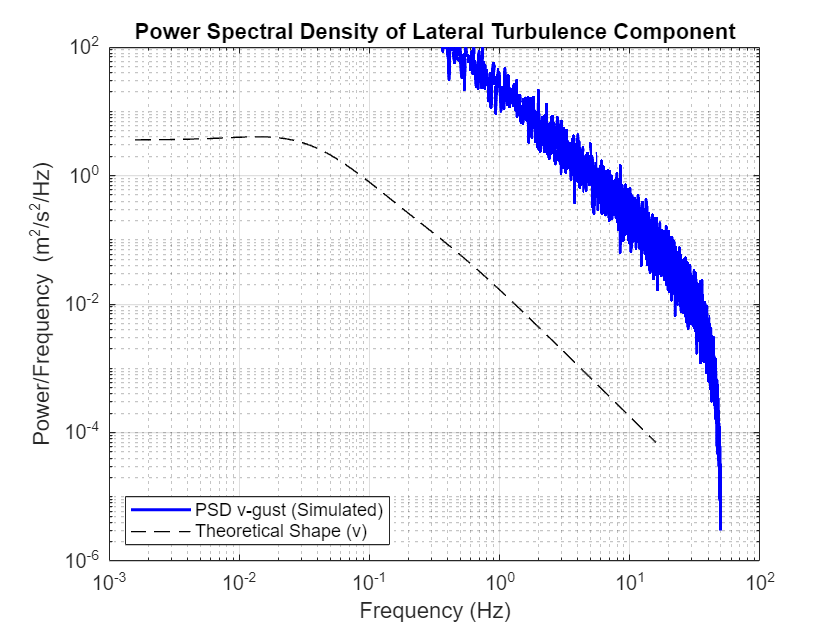


% Plot 2: Power Spectral Density of the filtered noise (the lateral gust)
figure('Name', 'Simulated Lateral Von Karman Gust PSD');

% Use Welch's method to estimate the PSD of the generated signal
[psd_v, freq_v] = pwelch(v_gust, [], [], [], fs);

% Plot the PSD on a log-log scale for better visualization
loglog(freq_v, psd_v, 'b', 'LineWidth', 1.5, 'DisplayName', 'PSD v-gust (Simulated)');
hold on;

% For validation, overlay the theoretical PSD shape from the transfer function
[mag_v, ~, w_v] = bode(Hv);

% The PSD is proportional to the magnitude squared of the frequency response
% We plot this to confirm the SHAPE of our simulated PSD is correct.
loglog(w_v/(2*pi), squeeze(mag_v).^2, 'k--', 'DisplayName', 'Theoretical Shape (v)');

title('Power Spectral Density of Lateral Turbulence Component');
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (m^2/s^2/Hz)');
legend('show', 'Location', 'southwest');
grid on;
ylim([1e-6 1e2]); % Adjust ylim to focus on the relevant power range


fprintf('Simulation complete. Check the generated figures.\n');

Simulation complete. Check the generated figures.


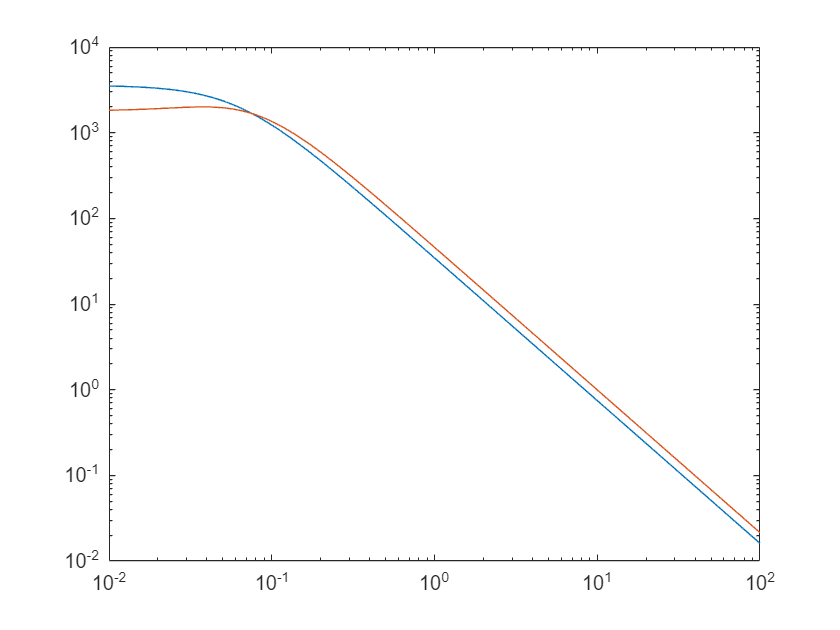


figure;
loglog(f, Phi_u_linear);
hold on;
loglog(f, Phi_v_linear);
% loglog(f, Phi_w_linear);
% loglog(w_v/(2*pi), squeeze(mag_v).^2, 'k--', 'DisplayName', 'Theoretical Shape (v)');
% loglog(freq_v, psd_v, 'b', 'LineWidth', 1.5, 'DisplayName', 'PSD v-gust (Simulated)');


hold off;

% Urban-modified longitudinal Bode (example)
omega = logspace(-2, 2, 1000);
L = 20; U = 10; omega_peak = U / L;
gain = 20;  % in dB

% Flattened urban roll-off and a bump at 1 rad/s
H_urban = gain - 10*log10(1 + (omega / omega_peak).^2) + ...
          5 * exp(-((log10(omega) - log10(1)).^2) / (2 * 0.1^2));  % resonance bump

figure;
bodemag(H_urban)
title("Modified von Kármán forming filter")
xlabel("Frequency (rad/s)")
ylabel("Magnitude (dB)")
